sadiasd

asdasd

asdasd

asdasd

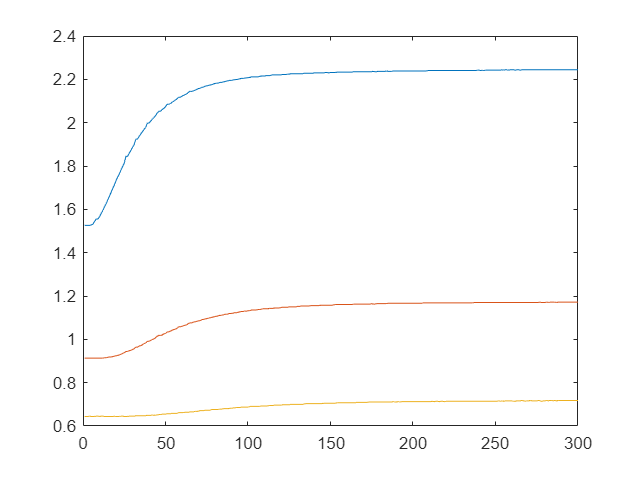

load("pomiary_3out.mat");
size(pomiary_3out);
czas = 1:1:300;
plot(czas, pomiary_3out);

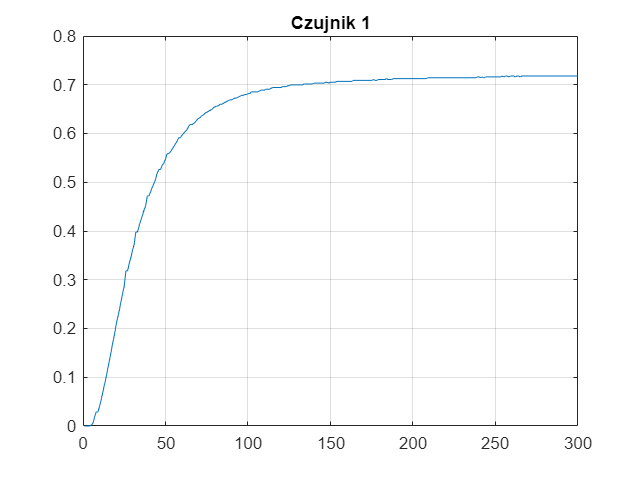

figure
y1=pomiary_3out(:,1) - pomiary_3out(1,1);
plot(czas, y1)
grid on
title("Czujnik 1")

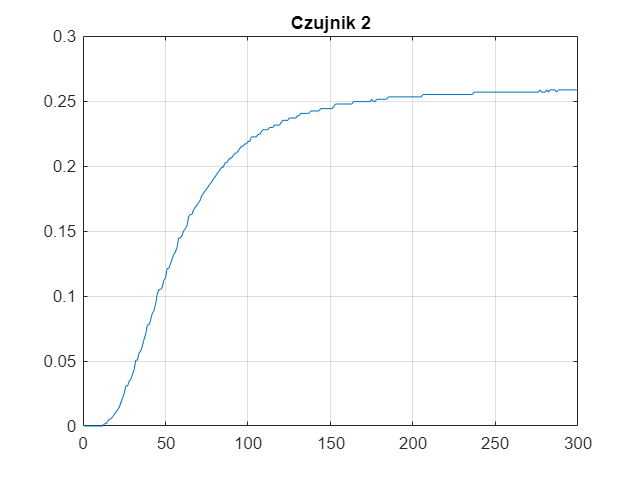

figure
y2=pomiary_3out(:,2) - pomiary_3out(1,2);
plot(czas, y2)
grid on
title("Czujnik 2")

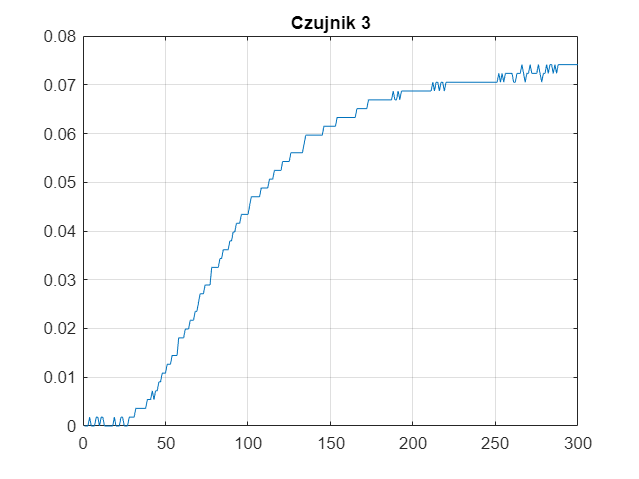

figure
y3=pomiary_3out(:,3) - pomiary_3out(1,3);
plot(czas, y3)
grid on
title("Czujnik 3")

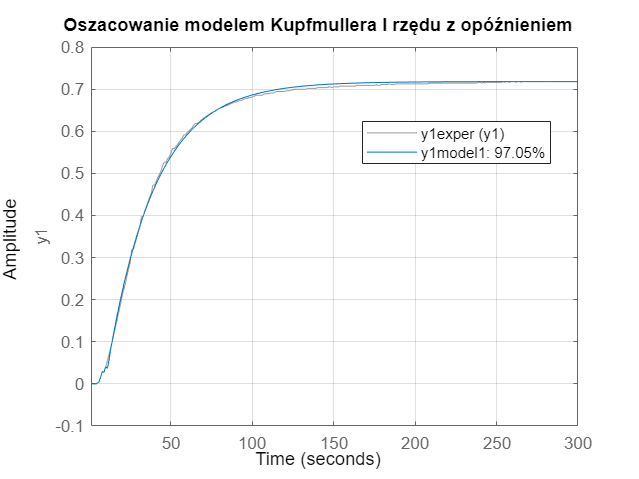

k1 = (y1(300,1)-y1(1,1))/1.0; %Wzmocnienie statyczne obiektu

tau = 7.5;
n = 10;
[ld,md]=pade(tau, n);

T = 29;  %Oszacowanie stałej czasowej
T1 = 4;
T2 = 28;
T1_2 = 16;
T2_2 = 20;

[l,m]=series(ld,md,[k1],[T,1]);  %model obiektu I rzędu z opóźnieniem
[l2, m2] = series (ld,md,[k1], [T1*T2, T1+T2, 1]);  %model obiektu II rzędu z opóźnieniem

l3 = [k1];
m3 = [T1_2*T2_2, T1_2 + T2_2, 1] ;  %model obiektu II rzędu bez opóznienia

y1m1 = step(l, m, czas);
y1m2 = step(l2, m2, czas);
y1m3 = step(l3, m3, czas);

u1 = ones(size(y1));
y1exper = iddata(y1, u1, 1);

y1model1 = tf(l, m);
y1model2 = tf(l2, m2);
y1model3 = tf(l3, m3);

compare(y1exper, y1model1, 300);  %funkcja porównująca
title("Oszacowanie modelem Kupfmullera I rzędu z opóźnieniem")
legend("Location", "best")
grid

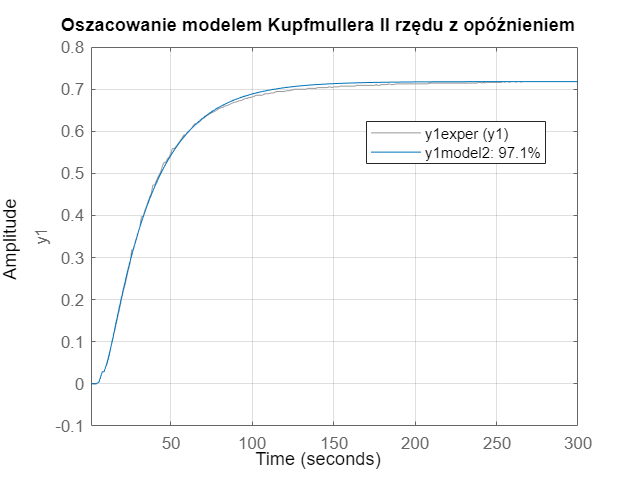

compare(y1exper, y1model2, 300);
title("Oszacowanie modelem Kupfmullera II rzędu z opóźnieniem")
legend("Location", "best")
grid

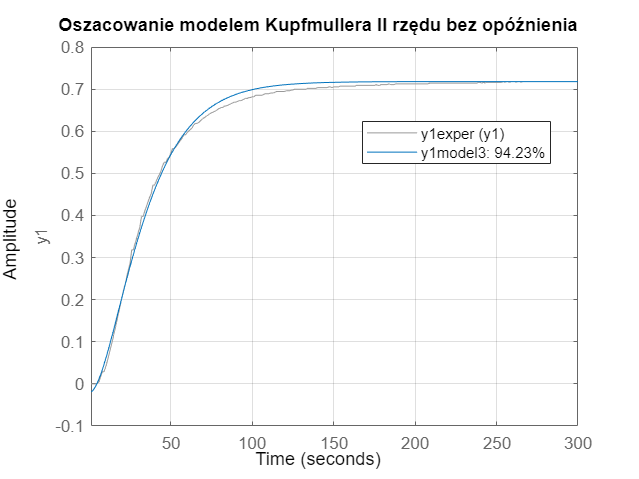

compare(y1exper, y1model3, 300);
title("Oszacowanie modelem Kupfmullera II rzędu bez opóźnienia")
legend("Location", "best")
grid

MSE1 = sum((y1-y1m1).^2)

MSE1 = 0.0432

MSE2 = sum((y1-y1m2).^2)

MSE2 = 0.0234

MSE3 = sum((y1-y1m3).^2)

MSE3 = 0.0408

Czujnik 2

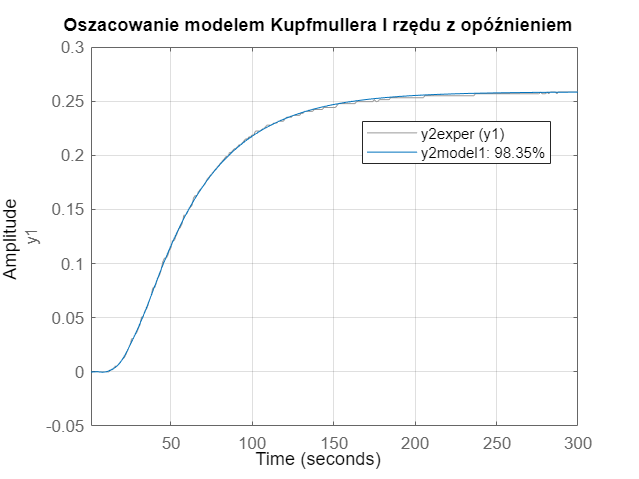

k2 = (y2(300,1)-y2(1,1))/1.0; %Wzmocnienie statyczne obiektu

tau = 50;
n = 10;
[ld,md]=pade(tau, n);

T = 40;  %Oszacowanie stałej czasowej
T1 = 28;
T2 = 35;
T1_2 = 26;
T2_2 = 30;

[l,m]=series(ld,md,[k2],[T,1]);  %model obiektu I rzędu z opóźnieniem
[l2, m2] = series (ld,md,[k2], [T1*T2, T1+T2, 1]);  %model obiektu II rzędu z opóźnieniem

l3 = [k2];
m3 = [T1_2*T2_2, T1_2 + T2_2, 1];   %model obiektu II rzędu bez opóznienia

y2m1 = step(l, m, czas);
y2m2 = step(l2, m2, czas);
y2m3 = step(l3, m3, czas);

u2 = ones(size(y2));
y2exper = iddata(y2, u2, 1);

y2model1 = tf(l, m);
y2model2 = tf(l2, m2);
y2model3 = tf(l3, m3);

compare(y2exper, y2model1, 300);  %funkcja porównująca
title("Oszacowanie modelem Kupfmullera I rzędu z opóźnieniem")
legend("Location", "best")
grid

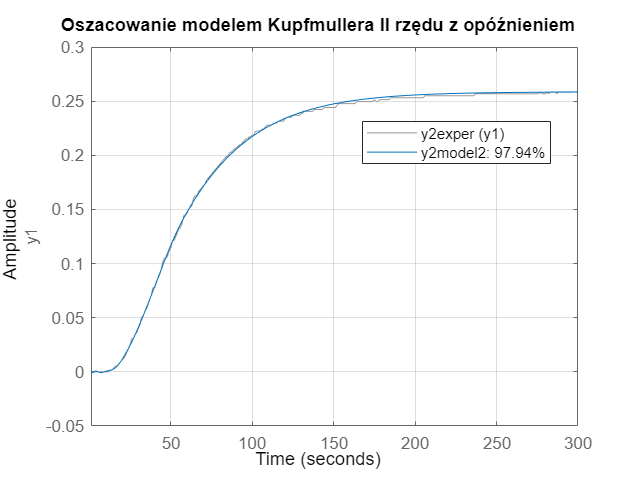

compare(y2exper, y2model2, 300);
title("Oszacowanie modelem Kupfmullera II rzędu z opóźnieniem")
legend("Location", "best")
grid

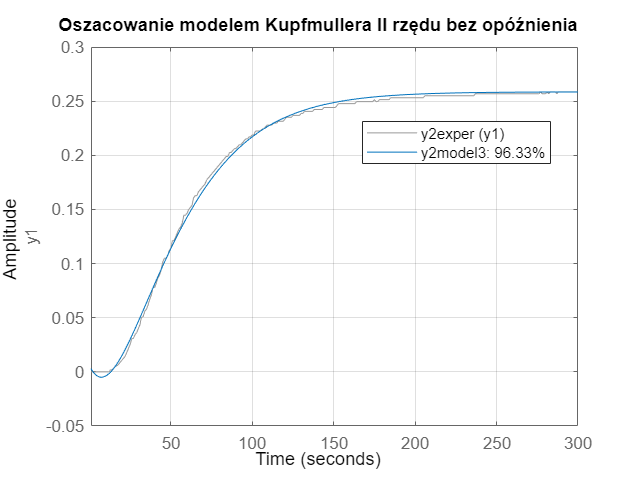

compare(y2exper, y2model3, 300);
title("Oszacowanie modelem Kupfmullera II rzędu bez opóźnienia")
legend("Location", "best")
grid

MSE1 = sum((y2-y2m1).^2)

MSE1 = 0.4094

MSE2 = sum((y2-y2m2).^2)

MSE2 = 1.1477

MSE3 = sum((y2-y2m3).^2)

MSE3 = 0.0457

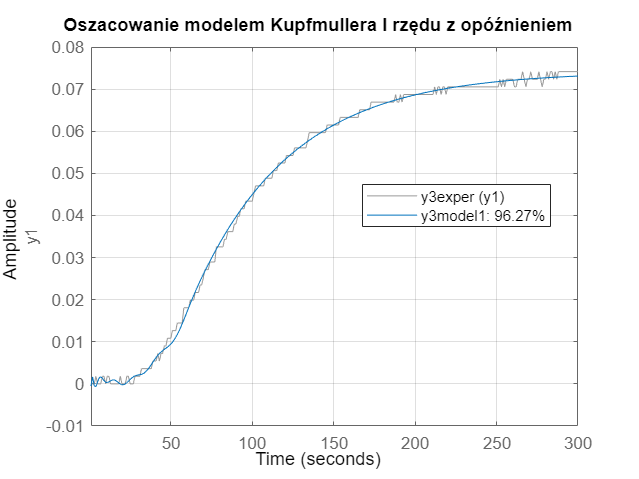

k3 = (y3(300,1)-y3(1,1))/1.0; %Wzmocnienie statyczne obiektu

tau = 50;
n = 10;
[ld,md]=pade(tau, n);

T = 60;  %Oszacowanie stałej czasowej
T1 = 38;
T2 = 40;
T1_2 = 41;
T2_2 = 43;

[l,m]=series(ld,md,[k3],[T,1]);  %model obiektu I rzędu z opóźnieniem
[l2, m2] = series (ld,md,[k3], [T1*T2, T1+T2, 1]);  %model obiektu II rzędu z opóźnieniem

l3 = [k3];
m3 = [T1_2*T2_2, T1_2 + T2_2, 1];  %model obiektu II rzędu bez opóznienia

y3m1 = step(l, m, czas);
y3m2 = step(l2, m2, czas);
y3m3 = step(l3, m3, czas);

u3 = ones(size(y3));
y3exper = iddata(y3, u3, 1);

y3model1 = tf(l, m);
y3model2 = tf(l2, m2);
y3model3 = tf(l3, m3);

compare(y3exper, y3model1, 300);  %funkcja porównująca
title("Oszacowanie modelem Kupfmullera I rzędu z opóźnieniem")
legend("Location", "best")
grid

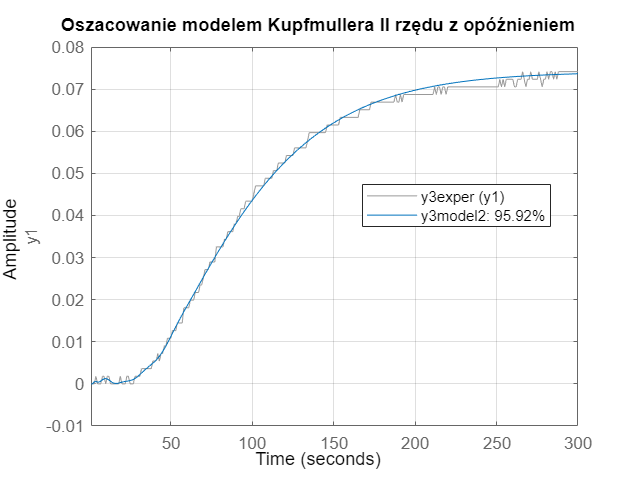

compare(y3exper, y3model2, 300);
title("Oszacowanie modelem Kupfmullera II rzędu z opóźnieniem")
legend("Location", "best")
grid

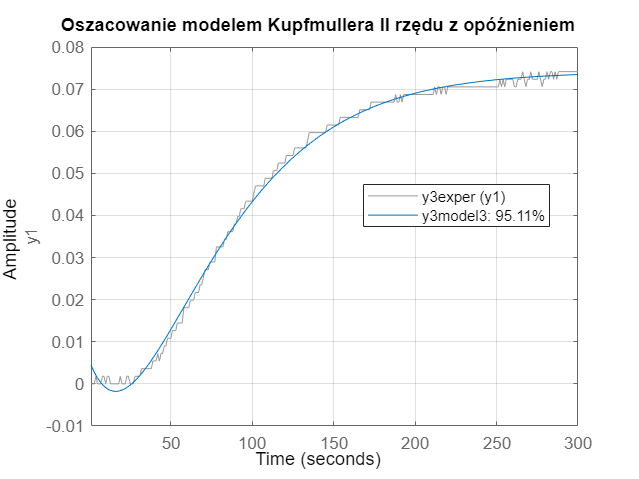

compare(y3exper, y3model3, 300);
title("Oszacowanie modelem Kupfmullera II rzędu z opóźnieniem")
legend("Location", "best")
grid

MSE1 = sum((y3-y3m1).^2)

MSE1 = 0.0026

MSE2 = sum((y3-y3m2).^2)

MSE2 = 0.0256

MSE3 = sum((y3-y3m3).^2)

MSE3 = 0.0114